# results visualization

## pred. distance v.s. true distance

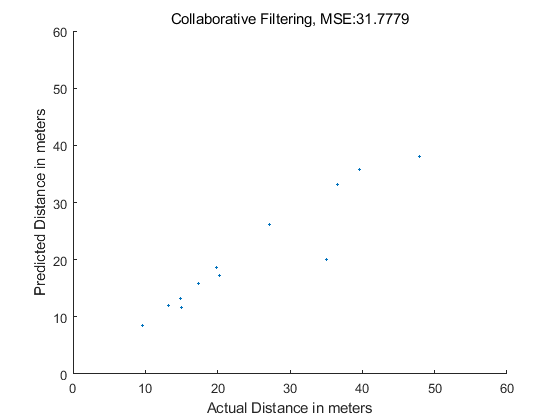

figure, 
scatter(y_trues, y_preds, 3, 'filled')
axis([0,60,0,60])
title(strcat('Collaborative Filtering, MSE: ', ...
num2str(sum((y_trues- y_preds).^2)/length(y_trues))))
xlabel('Actual Distance in meters'), ylabel('Predicted Distance in meters')

## distance estimation result visualization

% path
annotation_path = "E:\project\SCI_captioning\code\distance_estimation\CSENDistance\data\orig-data\test-data\chasing\annotations.csv";

% read csv
fid = fopen(annotation_path);
dcells = textscan(fid, '%f, %f, %f, %s');
fclose(fid);
dcellneeds = dcells(1:3);
Mat = cell2mat(dcellneeds);
disp(Mat);